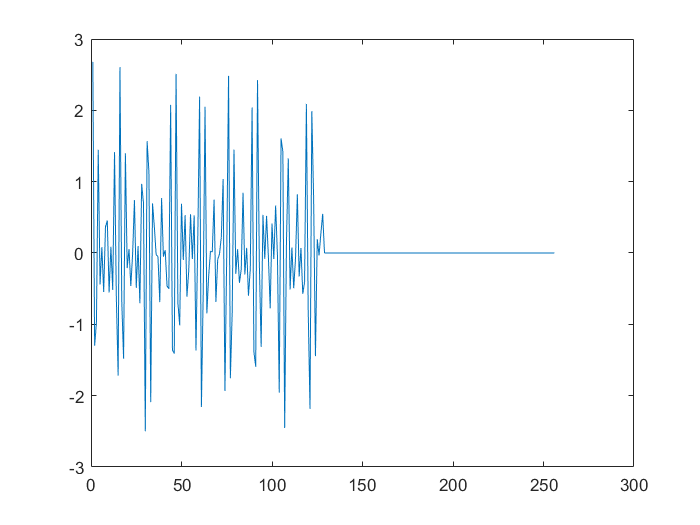

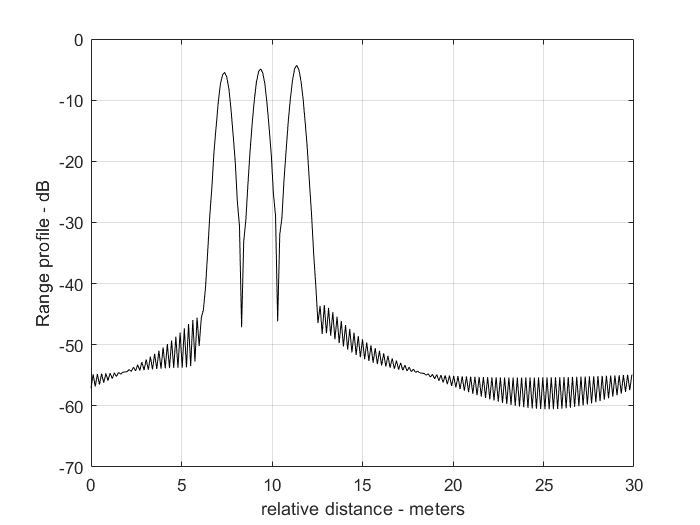

nscat = 3;
scat_range = [908, 910, 912];
scat_rcs = [0.7, 0.8, 0.9];
n = 128;
deltaf = 5e6;
prf = 10e3;
v = [50];
rnote = 900;
winid = 0;


hl = hrr_profile(nscat, scat_range, scat_rcs, n, deltaf, prf, v, rnote, winid);

%% 设置波形及目标参数
clear; close all;
c = 3e8; % 光速
fs = 200e6; % 采样率
f0 = 20e6; % 调制频率
tau = 5e-6; % 脉冲宽度
Bw = 20e6; % 带宽
v = 100; % 目标速度
R0 = 500; % 目标初始距离
R1 = 1000;
V1 = 100;
% t = 0:1/fs:2*tau; % 采样长度为一个脉冲周期
t = -tau:1/fs:tau;
N = length(t); % 帧内脉冲数
beta = Bw / (2*tau); % 调制系数
% sig_t = exp(j * pi * beta * t.^2); % 不含有载频发射脉冲
sig_t = exp(1j * 2 * pi * f0 * t + 1j * pi * beta * t.^2); % 含有载频的发射脉冲

## 生成回波信号 以及匹配滤波 两种方式 时域和频域

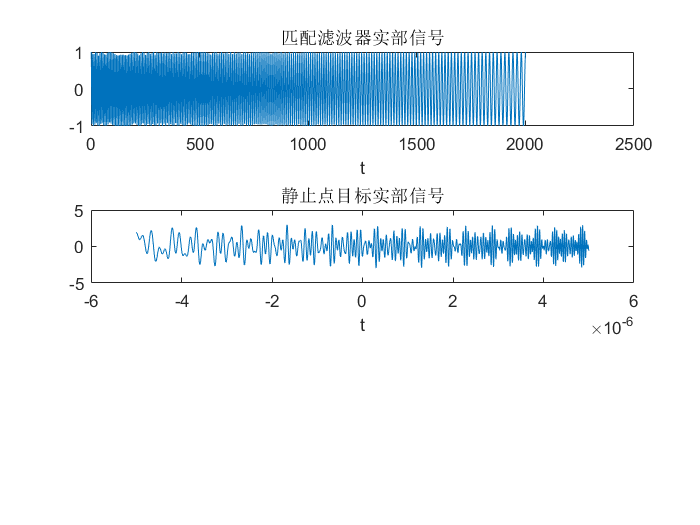

f = (-N/2:N/2 - 1)*fs/N;
% 静止点目标回波
taur = 2 * R0 / c; % 双程时延
tau2 = 2*(R0-150)/c;
tau3 = 2*(R0 + 230)/c;
% sig_r_static = exp(j * pi * beta * (t - taur).^2); % 不含有载频的脉冲
sig_r_static = exp(1j * 2 * pi * f0 * (t - taur) + 1j * pi * beta * (t - taur).^2);
sig_r_static = sig_r_static + exp(1j * 2 * pi * f0 * (t - tau2) + 1j * pi * beta * (t - tau2).^2);
sig_r_static = sig_r_static + exp(1j * 2 * pi * f0 * (t - tau3) + 1j * pi * beta * (t - tau3).^2);
taur2 = 2 * (R1 - V1*t)/2;
% sig_r_static = sig_r_static + exp(1j * pi * beta * (t - taur2).^2);
% 时域匹配滤波
ht = conj(fliplr(sig_t)); % 时域信号就是反折后求共轭
subplot(3, 1, 1)
plot(real(ht))
xlabel('t');title('匹配滤波器实部信号');
subplot(3, 1, 2)
plot(t, real(sig_r_static))
xlabel('t');title('静止点目标实部信号');

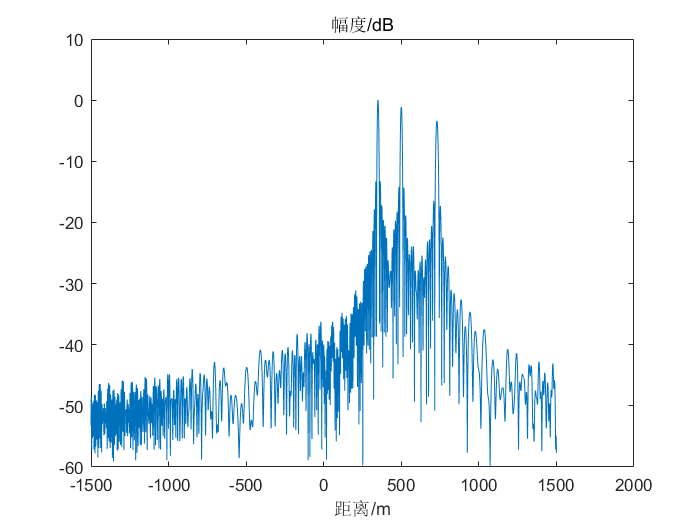

sig_r_fil = xcorr(sig_r_static, sig_t); % 求时域卷积
N_fil = 2 * N - 1;
% figure
t_fil = linspace(-tau, tau, N_fil);
% plot(t_fil * c, norm_dbv(sig_r_fil) + 10); % 可以观察到相对距离的变化
% 频域匹配滤波
Hf = fft(ht, 2*N);
sig_r_static_f = fft(sig_r_static, 2*N);
sig_r_fil_freq_domain = sig_r_static_f .* Hf;
sig_r_fil_time_domain = ifft(sig_r_fil_freq_domain, 2*N);
f2 = (-N:N - 1)*fs/ 2*N;
figure
plot(t_fil * c, norm_dbv(sig_r_fil_time_domain(1:length(sig_r_fil_time_domain)-1)));
xlabel('距离/m'); title('幅度/dB');

% 问题就是 在使用频域匹配滤波后，横坐标的偏移无法显示出偏移量 而且两个正好相反。。。。。。


## 加窗函数

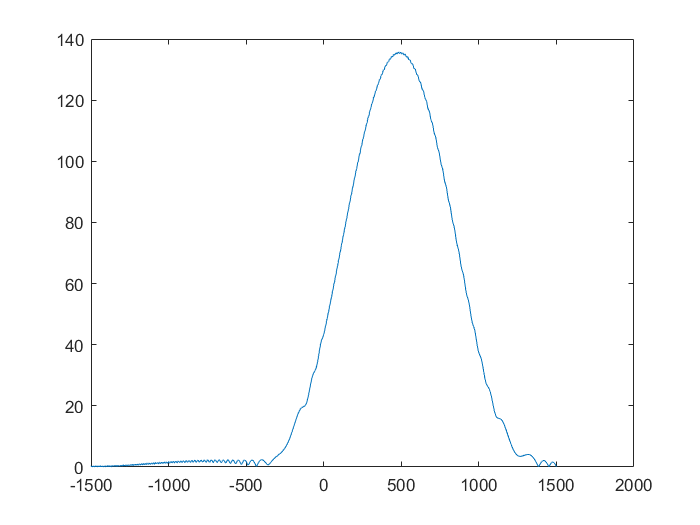

% Hanning 窗脉冲匹配滤波距离
win_l = length(sig_r_static);
h = zeros(1, win_l); % 窗函数的向量

win = hamming(win_l)'; % 窗口
h_win = ht.*win; % 对滤波器进行加窗处理
sig_r_static_lpf = exp(j * pi * beta * (t - taur).^2); % 
sig_r_static_win = sig_r_static_lpf.*h_win;

% 
% hfft_win = fft(h_win, 1024*8);
% sig_r_fil_win = abs(ifft(fft(sig_r_static, 1024*8).*hfft_win));
sig_r_fil_win = conv(sig_r_static_win, ht);
figure 
plot(t_fil * c, abs(sig_r_fil_win))

% 结论 加窗函数后会更平滑 副瓣会得到很好的抑制




## 对比正常的脉冲压缩（匹配滤波）和去斜处理的不同！！

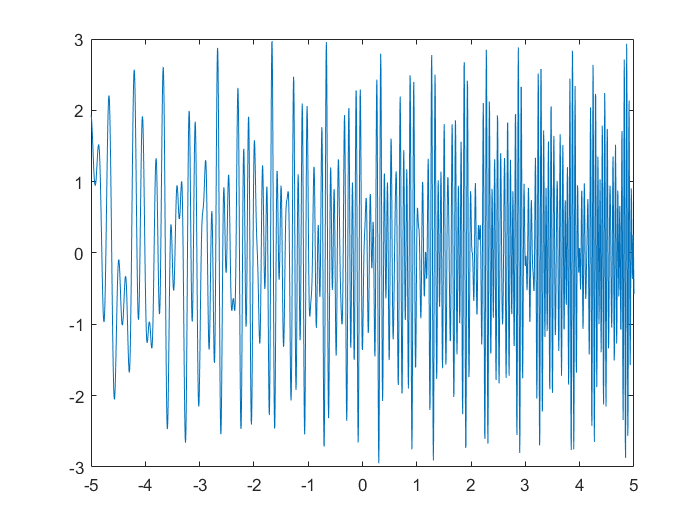

R_ref = 1300; % 参考距离
tau_ref = 2 * R_ref / c;
sig_ref = exp(1j * 2 * pi * f0 * (t) + 1j * pi * beta * (t - tau_ref).^2); % 参考信号
% 去斜
sig_ref = conj(sig_ref);
sig_stretch = sig_r_static .* sig_ref;
N_stretch = length(sig_stretch);
t_stretch = linspace(-tau, tau, N_stretch); 
figure
plot(t_stretch*1e6, real(sig_r_static));

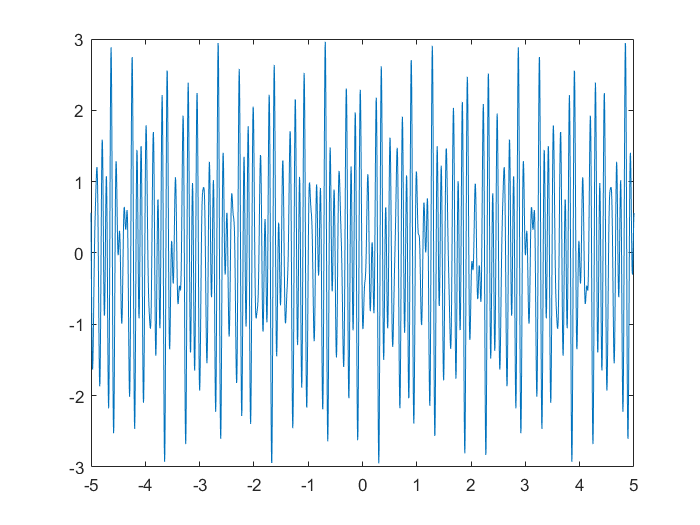

figure(10)
plot(t_stretch*1e6, real(sig_stretch))

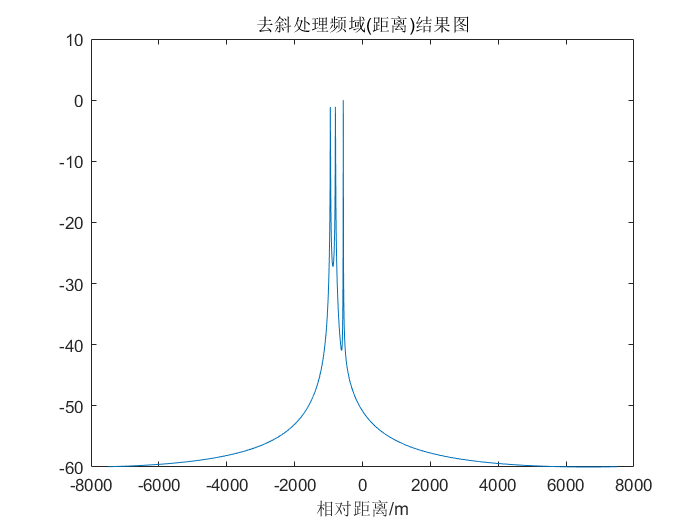

figure(11)
title('去斜后信号带宽')
f_stretch = (-N_stretch/2:N_stretch/2)* fs / (N_stretch);
rb = -f_stretch*c/beta/2;
plot(rb(1:2001), norm_dbv(fftshift(fft(sig_stretch))));
xlabel('相对距离/m'); title('去斜处理频域(距离)结果图')

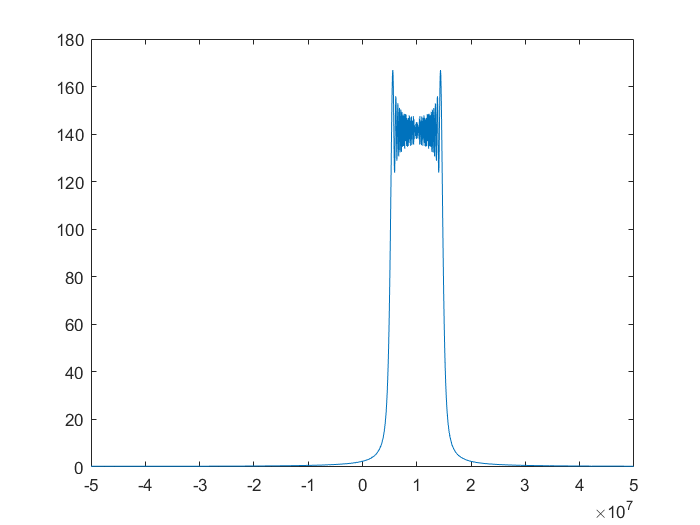

figure(12)
title('原始信号带宽')
f_t = (-N/2:N/2)*fs/(2*N); % 发射信号的频率横坐标
plot(f_t(1:2001), abs(fftshift(fft(sig_t))))

## 把去斜处理理论上的信号仿真一次

R0 = 300;
R1 = 100;
R2 = 1000;
ran = [300, 100, 1000];
t = 0:1/fs:2 * tau;
s_dechirp = zeros(1, length(t));
for i = 1:3
    range = ran(i);
    psi = 4.*pi*range*f0/c - ...
        4.*pi*Bw*range*range/c/c/(2*tau);
    psi2 = 4.*pi*Bw*range/c/(2*tau).*t;5 
    temp(i, :) = exp(i * psi + i .*psi2);
    s_dechirp = s_dechirp + temp(i, :);
end

ans = 5

ans = 5

ans = 5

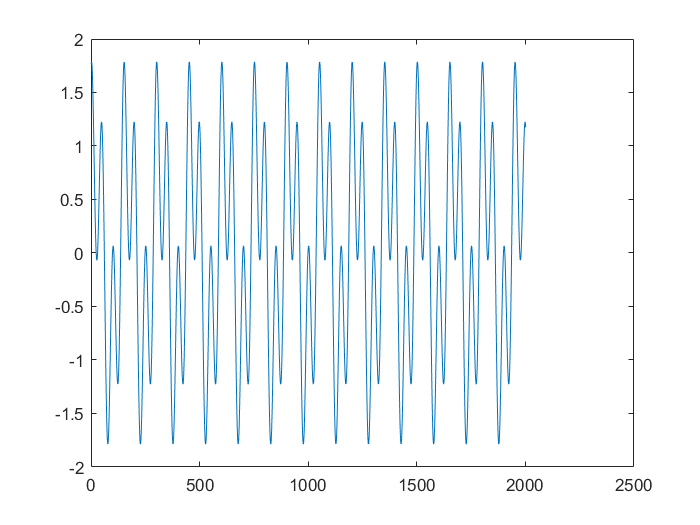

taur = 2 * R0/c;
taur2 = 2 * R1 / c;
s_dechirp = exp(1j * (pi * 2 * f0 * taur + 2 * pi * beta * taur * t - pi * beta * (taur)^2));
s_dechirp = s_dechirp + exp(1j * (pi * 2 * f0 * taur2 + 2 * pi * beta * taur2 * t - pi * beta * (taur2)^2));




figure(13)
title('理论去斜');
plot(real(s_dechirp))

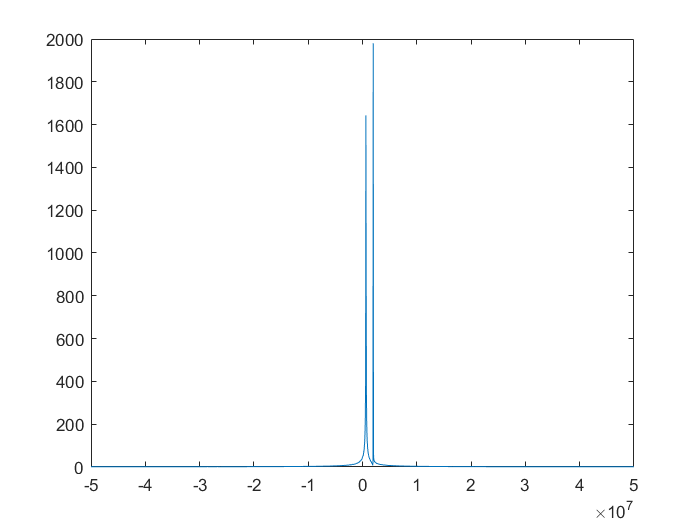

figure(14)
title('理论去斜频谱')
plot(f_t(1:2001), abs(fftshift(fft(s_dechirp))));

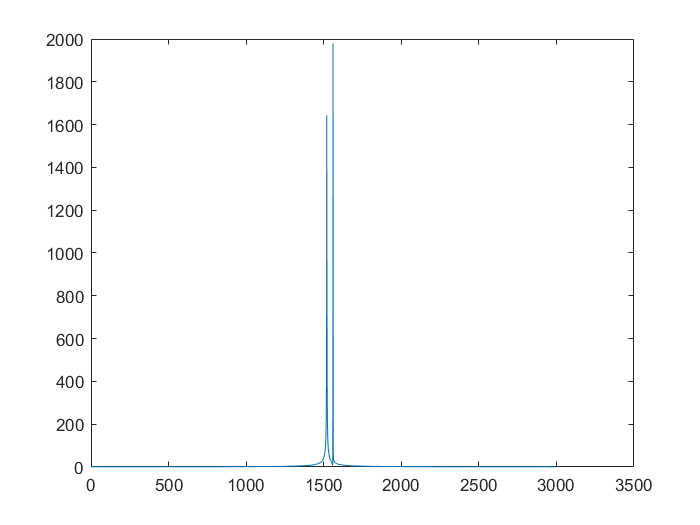

plot(t * c, abs(fftshift(fft(s_dechirp))));

function out = norm_dbv(in)
out = mapminmax(abs(in), 0, 1);
out = 20 * log10(out + 1e-3);
end


function [hl] = hrr_profile(nscat, scat_range, scat_rcs, n, deltaf, prf, v, rnote, winid)
    % nscat组成目标的散射体个数
    % scat_range 包含散射体距离的向量
    % 包含散射体RCS的向量
    % 步进数
    %% 参数设定
c = 3.0e8; % 光速
num_pulses = n; % 脉冲数目 步进个数 应该就是帧内脉冲数
SNR_dB = 10; % SNR dB
nfft = 256; % fft点数
carrier_freq = 9.5e9; % 初始频率Hz
freq_step = deltaf; % 步进频率
V = v; 
PRI = 1./prf; % 脉冲重复间隔
if (nfft > 2*num_pulses)
    num_pulses = nfft/2
else
end

%% 设定通道信号
Inphase = zeros((2*num_pulses), 1); % 同相信号
Quadrature = zeros((2*num_pulses), 1); % 正交信号
Inphase_tgt = zeros((2*num_pulses), 1); % 目标同相信号
Quadrature_tgt = zeros((2*num_pulses), 1); % 目标正交信号
IQ_freq_domain = zeros((2*num_pulses), 1); % IQ通道频域信号
Weighted_I_freq_domain = zeros(num_pulses, 1);
Weighted_Q_freq_domain = zeros(num_pulses, 1);
Weighted_IQ_time_domain = zeros((2*num_pulses), 1);
Weighted_IQ_freq_domain = zeros((2*num_pulses), 1);
abs_Weighted_IQ_time_domain = zeros((2*num_pulses), 1);
dB_abs_Weighted_IQ_time_domain = zeros((2*num_pulses), 1);
taur = 2.* rnote / c; % 每一个目标点的时延！！！非常关键的一下

for jscat = 1:nscat % 循环次数为目标点个数
    ii = 0;
    for i = 1:num_pulses
        ii = ii + 1;
        rec_freq = ((i-1) * freq_step); % recalculate frequancy 意思是重新计算当前脉冲的频率
        Inphase_tgt(ii) = Inphase_tgt(ii) + sqrt(scat_rcs(jscat)) * cos(-2*pi*rec_freq*(2.*scat_range(jscat)/c - 2*(V/c)*((i-1)*PRI + taur/2 + 2*scat_range(jscat)/c)));
        Quadrature_tgt(ii) = Quadrature_tgt(ii) + sqrt(scat_rcs(jscat)) * sin(-2*pi*rec_freq*(2*scat_range(jscat)/c - 2*(V/c)*((i-1)*PRI + taur/2 + 2*scat_range(jscat)/c)));
    end
end
if (winid >= 0)
    window(1:num_pulses) = hamming(num_pulses);
else
    window(1:num_pulses) = 1;
end
figure
plot(Inphase_tgt)
Inphase = Inphase_tgt;
Quadrature = Quadrature_tgt;
Weighted_I_freq_domain(1:num_pulses) = Inphase(1:num_pulses).*window';
Weighted_Q_freq_domain(1:num_pulses) = Quadrature(1:num_pulses).*window';
Weighted_IQ_freq_domain(1:num_pulses) = Weighted_I_freq_domain + Weighted_Q_freq_domain*j;
Weighted_IQ_freq_domain(num_pulses:2*num_pulses) = 0.+0.i;
Weighted_IQ_time_domain = (ifft(Weighted_IQ_freq_domain));
abs_Weighted_IQ_time_domain = (abs(Weighted_IQ_time_domain));
dB_abs_Weighted_IQ_time_domain = 20.0*log10(abs_Weighted_IQ_time_domain)+SNR_dB;
% calculate the unambiguous range window size
Ru = c /2/deltaf;
hl = dB_abs_Weighted_IQ_time_domain;

numb = 2*num_pulses;
delx_meter = Ru / numb;
xmeter = 0:delx_meter:Ru-delx_meter;
figure
plot(xmeter, dB_abs_Weighted_IQ_time_domain,'k')
xlabel ('relative distance - meters')
ylabel ('Range profile - dB')
grid
end

